# ASTR HW 7 

## PROBLEM 2

clear all
close all
clc

% Assigning the constants for calculation 
% Jupiter
M_j = 1.898*10^27;  % Mass [kg]
r_j = 7.783*10^8;  % Orbital radius [km]
G = 6.67*10^(-20);  % Gravitational constant [km^3/kg^2/s]
P_j = 4*pi^2*r_j^3/G/M_j;  % Period [s]

% Asteroid
P_a = 12*pi^2*r_j^3/5/G/M_j;  % Peroid [s]

## Sketching the two orbits

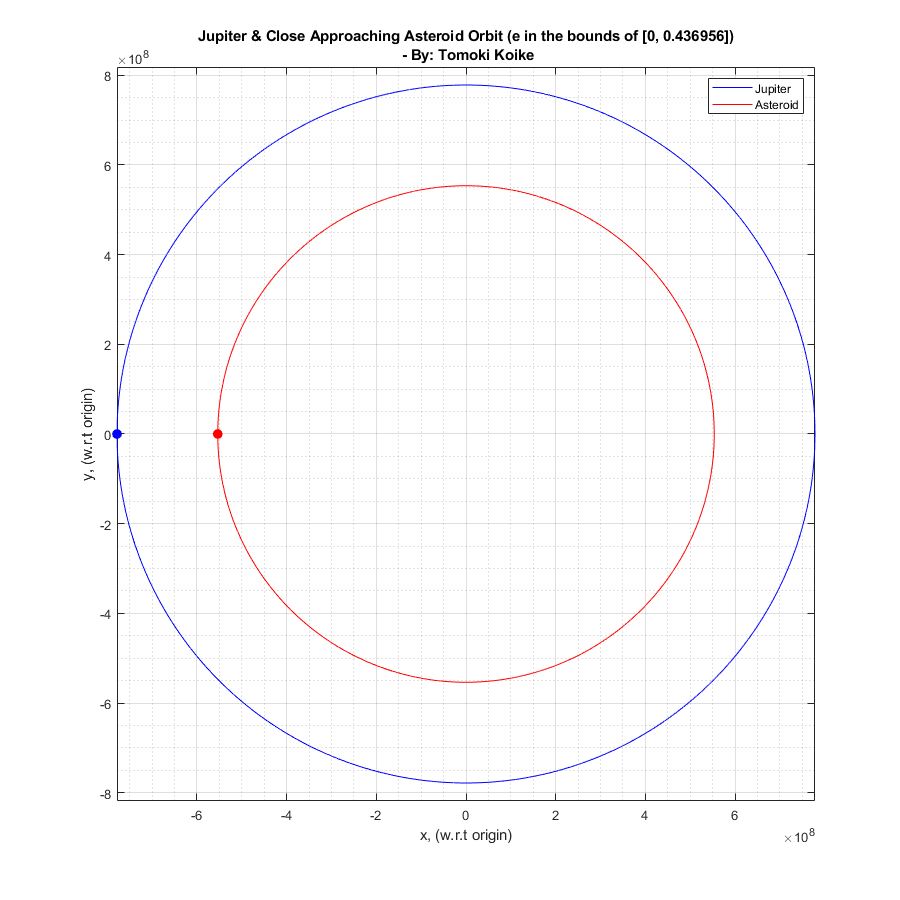

% Jupiter 
ang_span = linspace(0, 2*pi, 2^15);
R_j = r_j;
x_j = R_j.*cos(ang_span);
y_j = R_j.*sin(ang_span);

% Asteroid
R_a = r_j*(P_a^2/P_j^2)^(1/3);
x_a = R_a.*cos(ang_span);
y_a = R_a.*sin(ang_span);


% Plotting
figure('Renderer','painters','Position',[10 10 900 900])
plot(x_j, y_j, '-b', x_a, y_a, '-r')
title({'Jupiter & Close Approaching Asteroid Orbit (e in the bounds of [0, 0.436956])',['' ...
    ' - By: Tomoki Koike']})
xlabel('x, (w.r.t origin)')
ylabel('y, (w.r.t origin)')
hold on 
plot(R_j*cos(3*pi), R_j*sin(3*pi), '.b', 'MarkerSize', 25)
plot(R_a*cos(3*pi), R_a*sin(3*pi), '.r', 'MarkerSize', 25)
grid on
grid minor
box on
axis equal
legend('Jupiter', 'Asteroid')